# Projeto final - ES020

Bruno Monteiro Bonetti - 232488

## Extração dos dados

clc; clear all; close all;

% percorrendo todos os dados com um for, até achar meu RA

arquivo = load("projeto_ES020_2024s2.mat");

data = arquivo.dados;

meus_dados = [];

for i = 1:numel(data)
    dado_i = data{i};
    if isfield(dado_i, 'RA') && strcmp(dado_i.RA, '232488') 
        meus_dados = dado_i; 
        break; 
    end
end

m = meus_dados.m;
M = meus_dados.M;
g = meus_dados.g;
theta = meus_dados.exp1.theta;
t1 = meus_dados.exp1.t;
x = meus_dados.exp2.x;
t2 = meus_dados.exp2.t;

## Determinação de l

% figure;
% plot(t1, deg2rad(theta));
% xlabel("Tempo [s]");
% ylabel("Ângulo [rad]");
% grid("on");

% pelo gráfico identificamos que o período é de 1.888s
T = 1.888;

% fator de correcao K
theta_m = deg2rad(40);
m = (sin(theta_m/2))^2;
K = ellipticK(m);

% omega_n = (4 * K) / T;
omega_n = 2*pi/T;

% usando o fator de correção, a simulacao ficou distante do resultado
% experimental

l = 3*g/(2*omega_n^2)

l = 1.3286

## Determinação de k

% figure;
% plot(t2, x);
% xlabel("Tempo [s]");
% ylabel("Deslocamento [m]");
% grid("on");

% pelo grafico novamente identificamos o periodo
T_2 = 0.324;

w_n = 2*pi/T_2;

k = w_n^2 * M

k = 1.6923e+03

## Comparação da resposta do pendulo

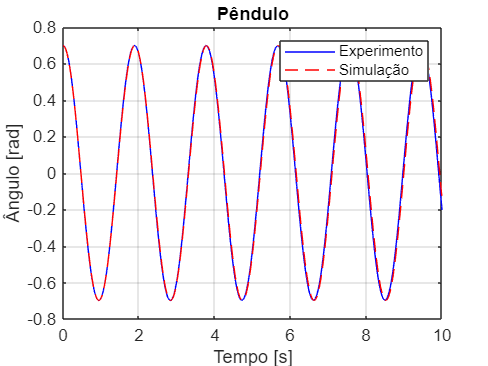

%reduzindo para um sistema de 1 ordem
f = @(t,y) [y(2) ; -3/2 * g/l * sin(y(1))];

cond_iniciais_pendulo = [0; deg2rad(40)];

%usando ode45 para resolver a edo
[t, theta_simulado] = ode45(f, t1, cond_iniciais_pendulo);

figure;
plot(t1, deg2rad(theta), 'b');
hold on;
plot(t1, theta_simulado(:,2), 'r--');
xlabel("Tempo [s]");
ylabel("Ângulo [rad]");
legend("Experimento", "Simulação");
grid("on");
title("Pêndulo");

## Comparação da resposta do carrinho

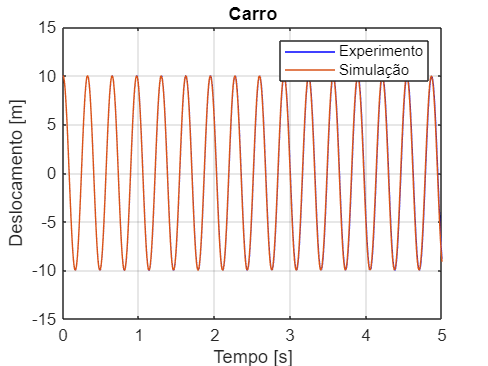

cond_iniciais_carro = [x(1); 0]; 

f_carro = @(t, y) [y(2); -k/M * y(1)];

[t_simulado_carro, x_simulado] = ode45(f_carro, t2, cond_iniciais_carro);

figure;
plot(t2, x, 'b');
hold on;
plot(t_simulado_carro, x_simulado(:, 1));
xlabel("Tempo [s]");
ylabel("Deslocamento [m]");
legend("Experimento", "Simulação");
grid on;
title("Carro");